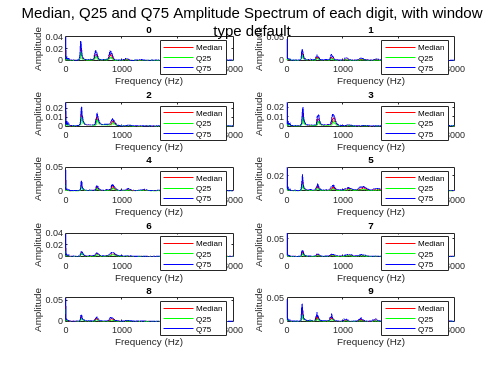

freqNum = 3000; % number of frequencies to plot
medianAmpSpectrumMat = zeros(freqNum, 10); % matrix to store the median amplitude spectrum of each digit
Q25AmpSpectrumMat = zeros(freqNum, 10); % matrix to store the 25th percentile amplitude spectrum of each digit
Q75AmpSpectrumMat = zeros(freqNum, 10); % matrix to store the 75th percentile amplitude spectrum of each digit
meanAmpSpectrumMat = zeros(freqNum, 10); % matrix to store the mean amplitude spectrum of each digit
everyAmpSpectrumMat = cell(10, 1); % matrix to store the amplitude spectrum of each digit

audioSignals = cell(50, 1); % Each one of the 50 samples will contain the audio signals of each one of the digits
for i = 1:50
    audioSignals{i} = preProcess(i-1); % get the audio signals of each one of the digits from the sample
end

[medianAmpSpectrumMat, Q25AmpSpectrumMat, Q75AmpSpectrumMat, meanAmpSpectrumMat, everyAmpSpectrumMat] = digitsAmpSpectrums(audioSignals, 'default');

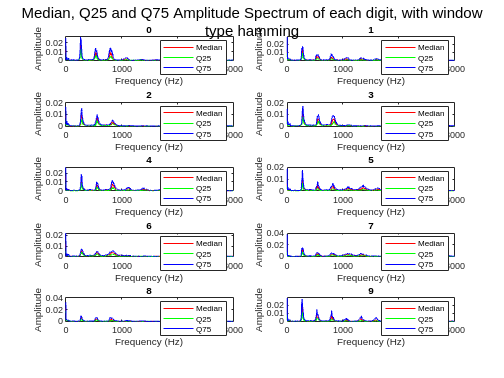


digitsAmpSpectrums(audioSignals, 'hamming');

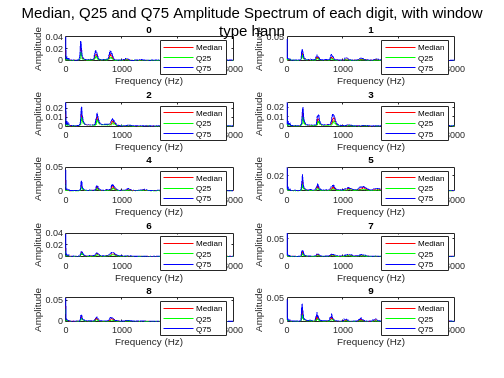

digitsAmpSpectrums(audioSignals, 'hann');

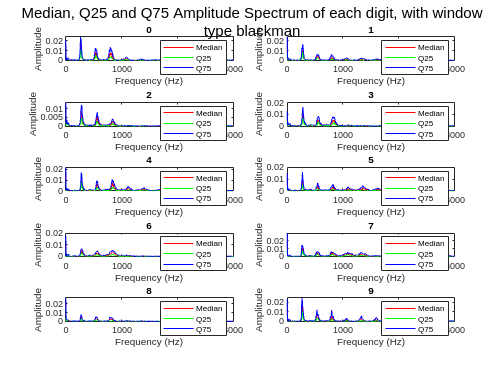

digitsAmpSpectrums(audioSignals, 'blackman');

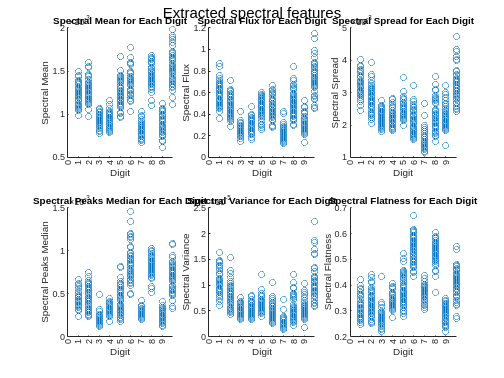


spectralFeatures = containers.Map(); % Hashmap containing the spectral features of each digit

% These arrays will store the spectral features of each sample of each digit
spectralMean = cell(10, 1);
spectralFlux = cell(10, 1);
spectralSpread = cell(10, 1);
spectralPeaksMedian = cell(10, 1);
spectralFlatness = cell(10, 1);
spectralVariance = cell(10, 1);

% These arrays will store the spectral features of each sample of the current digit
% So each index of the previous arrays will contain one of these arrays, forming a 50x10 matrix
curSampleSpectralMean = cell(50, 1);
curSampleSpectralFlux = cell(50, 1);
curSampleSpectralSpread = cell(50, 1);
curSampleSpectralPeaksMedian = cell(50, 1);
curSampleSpectralFlatness = cell(50, 1);
curSampleSpectralVariance = cell(50, 1);

% Iterate through every digit
for digit = 1:10
    % Iterate through every sample of the current digit
    for sample = 1:50
        % Calculate the diferent spectral features of the current sample of the current digit
        curSampleSpectralMean{sample} = mean(everyAmpSpectrumMat{digit}(:, sample), 1);
        curSampleSpectralFlux{sample} = sum(abs(diff(everyAmpSpectrumMat{digit}(:, sample))), 1); 
        curSampleSpectralSpread{sample} = std(everyAmpSpectrumMat{digit}(:, sample), 1);
        curSampleSpectralPeaksMedian{sample} = median(findpeaks(everyAmpSpectrumMat{digit}(:, sample)), 1);
        curSampleSpectralFlatness{sample} = geomean(everyAmpSpectrumMat{digit}(:, sample)) / mean(everyAmpSpectrumMat{digit}(:, sample));
        curSampleSpectralVariance{sample} = var(everyAmpSpectrumMat{digit}(:, sample), 1);
    end
    % Store the spectral features of the current digit after iterating through all the samples
    spectralMean{digit} = curSampleSpectralMean;
    spectralFlux{digit} = curSampleSpectralFlux;
    spectralSpread{digit} = curSampleSpectralSpread;
    spectralPeaksMedian{digit} = curSampleSpectralPeaksMedian;
    spectralFlatness{digit} = curSampleSpectralFlatness;
    spectralVariance{digit} = curSampleSpectralVariance;
end

% Store the 50x10 matrix of spectral features in an hashmap for easy access
spectralFeatures('Spectral Mean') = spectralMean;
spectralFeatures('Spectral Flux') = spectralFlux;
spectralFeatures('Spectral Spread') = spectralSpread;
spectralFeatures('Spectral Peaks Median') = spectralPeaksMedian;
spectralFeatures('Spectral Variance') = spectralVariance;
spectralFeatures('Spectral Flatness') = spectralFlatness;

spectralFeaturesStrings = {'Spectral Mean', 'Spectral Flux', 'Spectral Spread', 'Spectral Peaks Median', 'Spectral Variance', 'Spectral Flatness'};

% Scatterplot every feature
figure; 
annotation('textbox', [0 0.9 1 0.1], 'String', ['Extracted spectral features'], 'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontSize', 15);
for i = 1:6
    % Create a scatter plot
    subplot(2, 3, i);
    scatterplotFeature(spectralFeatures(spectralFeaturesStrings{i}), spectralFeaturesStrings{i}, strcat(spectralFeaturesStrings{i}, ' for Each Digit'));
end

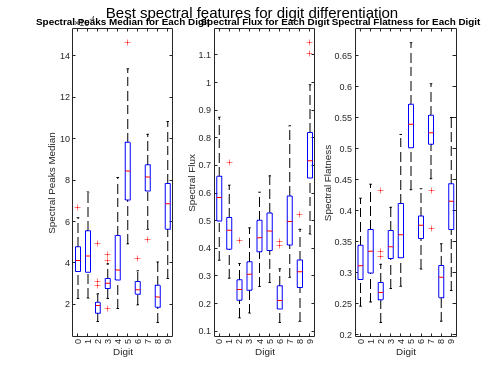


spectralBestFeaturesStrings = {'Spectral Peaks Median', 'Spectral Flux', 'Spectral Flatness'};
% Boxplot the 3 beast features
figure;
annotation('textbox', [0 0.9 1 0.1], 'String', ['Best spectral features for digit differentiation'], 'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontSize', 15);
for i = 1:3
    % Make a boxplot of the spectral mean of each digit
    subplot(1, 3, i);
    boxplotFeature(spectralFeatures(spectralBestFeaturesStrings{i}), spectralBestFeaturesStrings{i}, strcat(spectralBestFeaturesStrings{i}, ' for Each Digit'));
end